## **Impacts of Prevention Strategies on Subsequent Waves of Influenza Infection for Immunocompromised and Non Immunocompromised Individuals**

### (IPSSWIIINII) 

#### Written by: KD Duong, Jessica Brown

## **Question**: 

***What impacts do certain prevention strategies have on Influenza infection waves?***

We are answering a design question to investigate intervention strategies for combating subsequent waves of influenza infection. Answering this question is important because it will help physicians and virologists implement the most effective prevenetion strategy for this problem. 

We will be learning about the impact of two main intervention strategies: vaccinations and exposure prevention methods (washing hands, PPE, etc). The intervention strategies will be applied to two populations: immunocompromised and non immunocompromised people. 

## **Methodology/Model:**

By using stock and flow models, equations, MATLAB simulations and interpretations, we were able to compare the effectiveness of the intervention strategies for both populations. 

**Stock and Flow:**

By adding an additional flow to the traditional ISR model, we were able to demonstrate the impacts of a mutation on the population. Specifically, we implemented a flow that runs from the recovered stock back to the susceptible stock. 

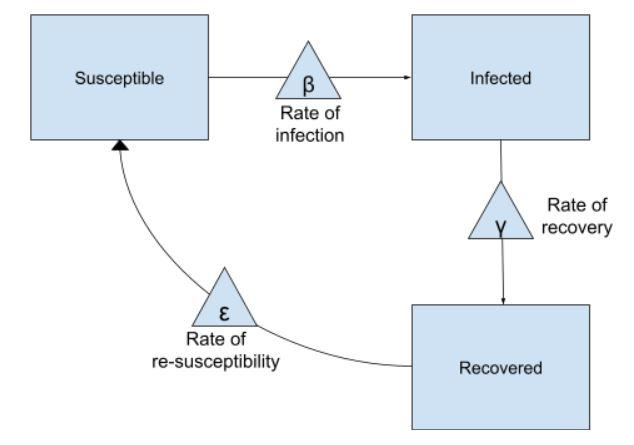

**Equations:**

We developed an equation for modelling the new flow between the Recovered and Susceptible stocks. 

*Equation for modelling the flow of re-susceptibility between recovered and susceptible stocks:*

**S = S + (****ε**** * R)**

**R = R - (****ε**** * R)**

S = Susceptible stock 

R = Recovered stock

**ε **= Rate of re-suscebtibility, reflecting the flow that would occur as a result of a mutation in Influenza 

We also developed an equation for representing the impact of a vaccination on infection rate. 

*Equation for modelling the decrease in infection rate caused by a vaccination by multiplying the existing infection rate by a low percentage: *

**V = β * Vac**

V = Infection rate with vaccine 

**β** = Initial infection rate

Vac = Factor we multiply **β** by to decrease infection rate

**Assumptions:**

Good Assumptions:

- We assumed that immunocompromised individuals would be more susceptible to contracting Influenza than the general population. This makes sense because immunocompromised people have weakened immune systems, and are therefore, more likely to become sick from subsequent variations of Influenza.

- We assumed that people would alrady be implementing exposure prevention methods in the beginning of the model testing the impacts of exposure prevention. This makes sense because people would already be washing their hands and implementing some form of exposure prevenetion in their lives before being advised to do so by health professionals.

Bad Assumptions:

- We assumed that everyone would be equally susceptible to Influenza when they are in their respective groups. This is not true in reality; however, it was implemented to make the model simpler. We thought about using agent-based modeling, but this falls outside of the scope of the project/class. 

- The numbers used for our variables are arbitrary and do not reflect data from the real world. For example, the infection rate of Influenza and the recovery rate were not based on data. We used abductive reasoning to determine numbers for our variables that would make sense. 

**Parameters:**

The stocks for both of the populations are represented in immuno_stock and regular_stock. These hold the initial number of individuals in the susceptible stock. Infected_0 denotes the initial number of individuals in the infected stock, and is used to begin the model for both of the populations. 

As mentioned before, the values of the variables we used were not based on research but on abductive reasoning. We defined the variables at the top of our script and then passed them into the functions as parameters. These variables include, with *X* denoting either the immunocompromised or non-immunocompromised population: 

- **X_infection_rate** = rate at which the people from the susceptible stock flow into the infected stock for a specific population

- **X_recovery_rate** = rate at which people from the infected stock flow into the recovered stock for a specific population

- **X_rec2susc** = rate at which people from the recovered stock flow back into the susceptible stock for a specific population

- **X_vac_in_rate** = the percent at which the infection rate is multiplied by to repesent a population receiving a vaccine (decreases the infection rate)

figure 
hold on 
clf

% Stocks:
immuno_stock = 99;
infected_0 = 1;
regular_stock = 99; 

% Rates:
immuno_infection_rate = .55;
regular_infection_rate = .2;

immuno_recovery_rate = .2;
regular_recovery_rate = .25;

regular_rec2susc = .15;
immuno_rec2susc = .65;

regular_vac_in_rate = .1;
immuno_vac_in_rate = .05;

**Development and Refinement:**

At first, we wrote distinct functions for each of our simulations. Then we learned that we could pass parameters into functions instead of hard coding values. We changed our hard-coded infection rate and vaccine efficacy rate to variables so that we could reuse the same functions to model several situations.

For example, rather than creating separate functions for simulating intervention strategies between immunocompromised and non-immunocompromised people, we used the same function and passed in separate infection rates and vaccination efficacy rates for each to gather data about the effects of the same intervention strategies on distinct populations.

We used this line to call the vaccine simulation function and we pass in the aforementioned parameters. The full function is shown in the bottom of the live script. 

*[S, I, R, W] = sir_simulate_vac(regular_stock,infected_0,0,regular_infection_rate,regular_recovery_rate, 52,regular_rec2susc,regular_vac_in_rate);*

*Pseudocode:*

*results = function(susceptible stock, infected stock, recovered stock, infection rate, recovery rate, number of weeks, recovery to susceptible rate, vaccination efficacy);*

**Verification:**

We verified our model by comparing the results we obtained for the control graphs and intervention strategy implementation graphs. We knew that the changes we implemented in the functions that modeled intervention strategies should differentiate from the control plot. However, we found that sometimes the changes we implemented had no effect on the graphical outcomes on each of the plots. 

For example, when we were graphing the effects of intervention strategies on immunocompromised people, we found that there was no difference between the control and intervention plots. We increased the vaccine efficacy rate to see whether that would make an impact on the number of individuals who became infected with subsequent strains of influenza. 

After increasing the vaccine efficacy rate by a large margin, we detected a notable difference between the infected stock in the control simulation plot and the intervention strategy plot, meaning that virologists would have to make a vaccine extremely effective for it to successfully combat influenza infection in the immunocompromised population. 

## **Results:**

The model generates multiple graphs which can be used to compare the different prevention strategies with the populations. These graphs show the differences in effectiveness, overall illustrating that being vaccinated and using exposure prevention methods at the same time are superior to only doing one of the strategies alone. 

This first set of code defines variables (stocks and flow numbers) and plots the control graph (no strategies happen here).

% Run simulation
[S, I, R, W] = sir_simulate_v2(regular_stock,infected_0,0,regular_infection_rate,regular_recovery_rate, 52,regular_rec2susc);

% Plot 1 - Control 
figure(1); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

title('Control for Non-Immunocompromised People')
xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})

The following code implements the vaccination strategy at week 25. 

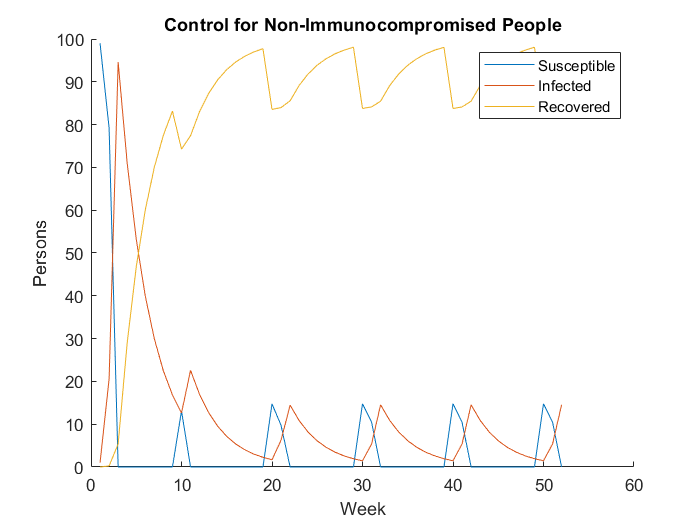

% Run simulation
[S, I, R, W] = sir_simulate_vac(regular_stock,infected_0,0,regular_infection_rate,regular_recovery_rate, 52,regular_rec2susc,regular_vac_in_rate);

% Plot 2 - with Vaccine implemented at week x
hold off

figure

figure(2); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

title(['Impact of Influenza on Non-Immunocompromised' newline 'Population with Vaccine Over Time'])
xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})


The following code implements the exposure prevention strategy. In the beginning of the model, there is already a low degree of the strategy being implemented. At week X, the strategy proliferates to a higher degree.

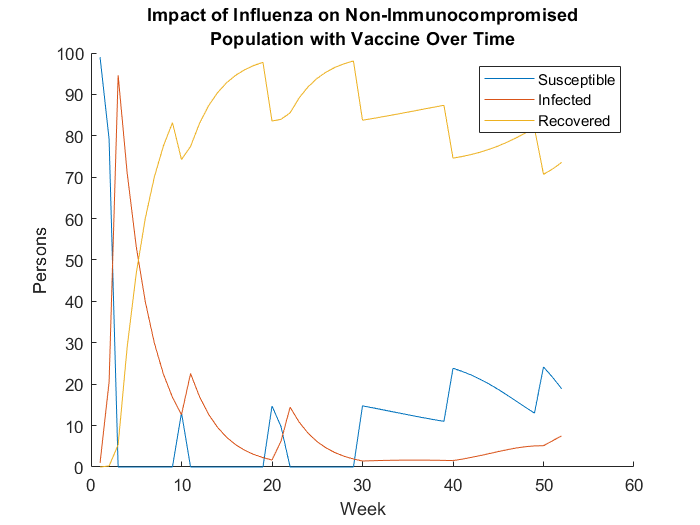

% Run simulation
[S, I, R, W] = sir_simulate_exp(regular_stock,infected_0,0,regular_infection_rate,regular_recovery_rate, 52,regular_rec2susc);

% Plot 3 - with exposure prevention at week 0 and increases at week x
hold off

figure

figure(3); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

title(['Impact of Influenza on Non-Immunocompromised' newline 'Population with Exposure Prevention Over Time'])
xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})

The following code implements both the vaccination strategy and the exposure prevention strategy at the same time. First, a small degree of exposure prevention is implemented at the start of the model. Then, the exposure prevention increases in week X, and finally, the vaccination is given out at week X_2. 

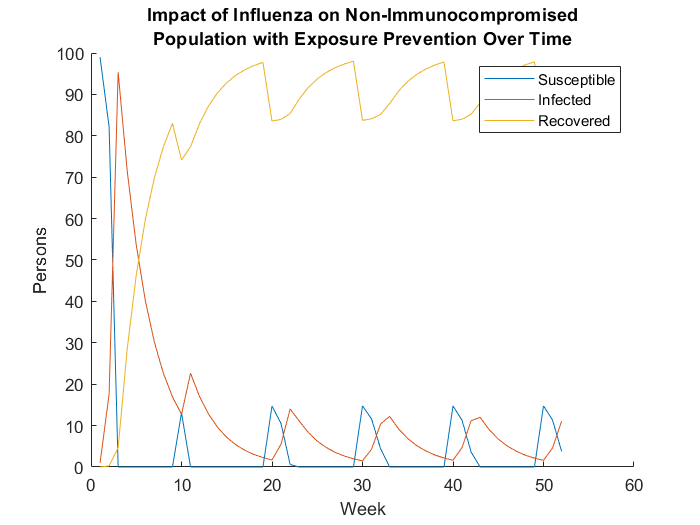

% Run simulation
[S, I, R, W] = sir_simulate_Vaccexp(regular_stock,infected_0,0,regular_infection_rate,regular_recovery_rate, 52,regular_rec2susc,regular_vac_in_rate);

% Plot 4 - with exposure prevention at week 0 and increases at week
% x along with vaccine at week x_2
hold off

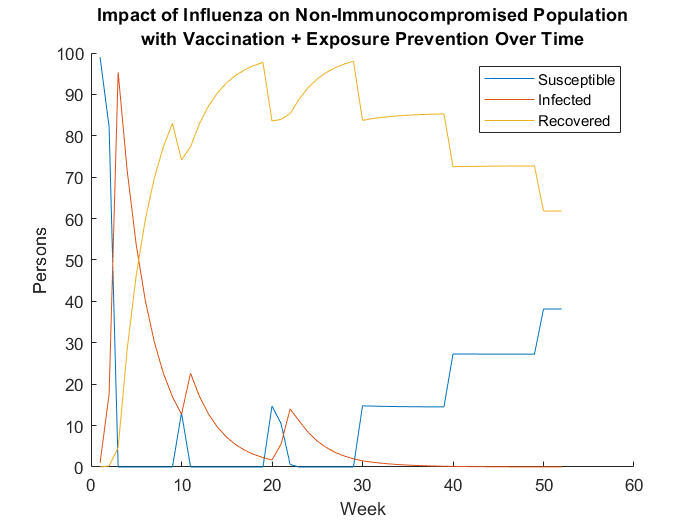

figure

figure(4); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

title(['Impact of Influenza on Non-Immunocompromised Population' newline 'with Vaccination + Exposure Prevention Over Time'])
xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})

The following code runs the same set of lines from above but on the immunocompromised population instead of the regular/non-immunocompromised population.

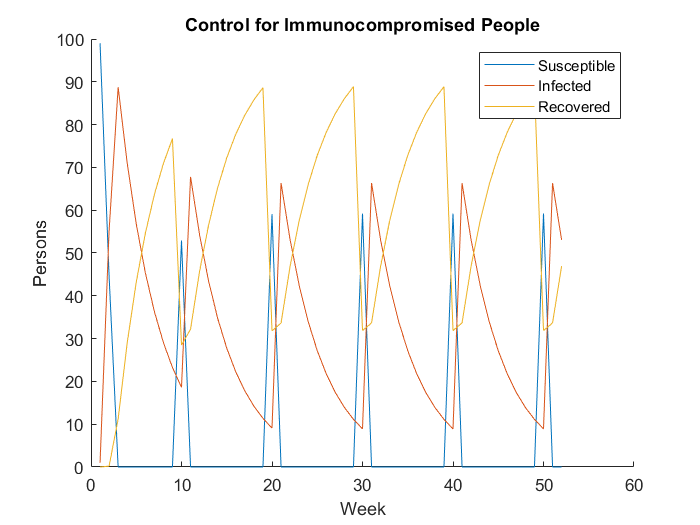

% Run simulation - Immuno
[S, I, R, W] = sir_simulate_v2(immuno_stock,infected_0,0,immuno_infection_rate,immuno_recovery_rate, 52,immuno_rec2susc);

% Plot 1 - Control 
figure(5); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

title('Control for Immunocompromised People')
xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})

Vaccination Simulation:


[S, I, R, W] = sir_simulate_vac(immuno_stock,infected_0,0,immuno_infection_rate,immuno_recovery_rate, 52, immuno_rec2susc,immuno_vac_in_rate);
% Plot 2 - Immuno Vac 
figure(6); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

title(['Impact of Influenza on Immunocompromised' newline 'Population with Vaccine Over Time'])
xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})


Exposure Prevention:

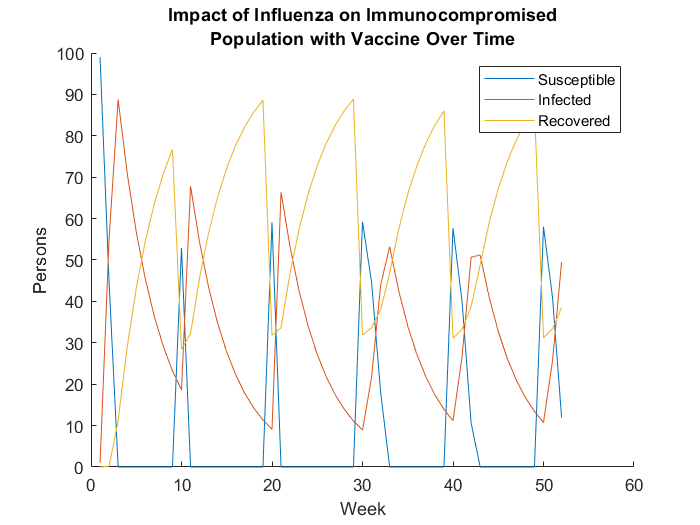


[S, I, R, W] = sir_simulate_exp(immuno_stock,infected_0,0,immuno_infection_rate,immuno_recovery_rate, 52,immuno_rec2susc);
% Plot 3 - Immuno with exposure prevention at week 0 and increases at week x
hold off

figure

figure(7); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

title(['Impact of Influenza on Immunocompromised' newline 'Population with Exposure Prevention Over Time'])
xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})


Vaccine and Exposure Prevention:

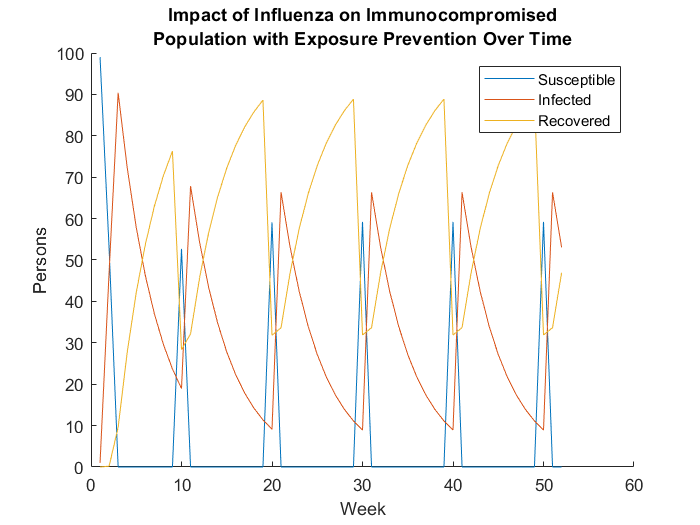


[S, I, R, W] = sir_simulate_Vaccexp(immuno_stock,infected_0,0,immuno_infection_rate,immuno_recovery_rate, 52,immuno_rec2susc,immuno_vac_in_rate);
% Plot 4 - Immuno with exposure prevention at week 0 and increases at week
% x along with vaccine at week x_2
hold off

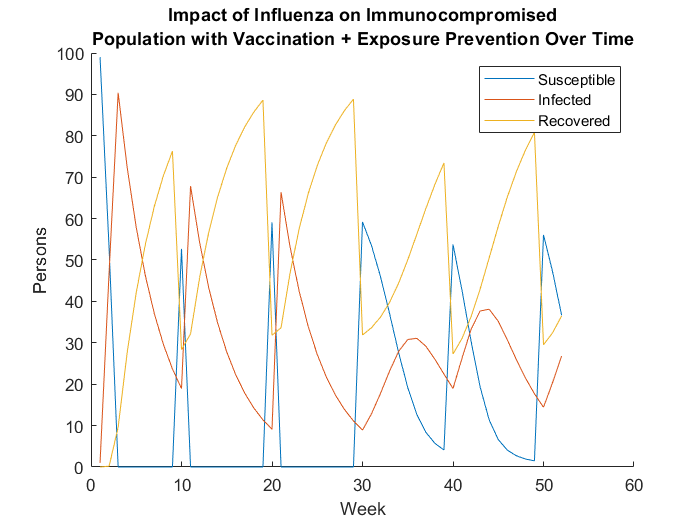

figure

figure(8); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

title(['Impact of Influenza on Immunocompromised' newline 'Population with Vaccination + Exposure Prevention Over Time'])
xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})

## **Interpretations and Reflections:**

**Key Points:**

- In each plot, our results reflect a decrease in the infected stock over subsequent waves of infection, indicating that the vaccination and exposure prevention methods are effective interventions strategies. 

- In the function that executes the vaccine simulation, we programmed the vaccine to be implemented at week 25. We implemented the vaccination strategy by decreasing the infection rate by a vaccine efficacy rate. Therefore, we expected to see declines in the number of infections in subsequent waves of Influenza after week 25. This behavior matches the results we observed in our plots. Therefore, because the vaccination strategy decreased the number of infections in subsequent waves of the Influenza outbreak, we determined vaccination is a successful intervention strategy. 

- The same process was used to model the effects of an exposure prevention strategy. Rather than decreasing the infection rate by a vaccine efficacy rate, we decreased the infection rate by a factor that reflects exposure prevention. We observed the same downward trend in infections after week 25 in the plots reflecting the exposure prevention strategy. 

- We also compared our control results to our intervention strategy results to determine that the vaccination and exposure prevention strategies were effective. The number of people in the infected stock in our controls did not decrease across subsequent waves. However, after implementing our prevention strategies, we observed a downward trend in the number of people infected with subsequent strains of influenza. 

- We also decided to create a plot that reflects the combined intervention strategies. When the intervention strategies were combined, we found that they were even more effective at reducing infections by a significant margin as compared to how effective they were independently. 

The results/graphs illustrate the effectiveness of each prevention strategy on both populations. When comparing the graphs to each other and viewing the changes in the number of infected people after the strategies were implemented, a large difference in number of people infected can be seen. The differences show that when the two strategies worked together, it served to be more effective than only doing the vaccine or the exposure prevention methods alone. 

We believe the answers turned out to be a good result because we were able to demonstrate the impact of prevention strategies on the mutation waves of Influenza. Our model also illustrated the best impact would be to combine both vaccinations and exposure prevention methods together. 

Even though this model did what we wanted it to do, there are certain limitations to the model. The model is not accurate. As mentioned beforehand, the values of our variables are not based on real data/numbers, thus making this model not applicable in a real-world setting. Furthermore, our 'bad' assumptions add onto the limitations of our model since realistically, a group of people will have a varying resistance to certain illnesses. 

**Reflections:**

In the future, we would develop our model in various ways:

- We would definitely base our model on actual data that would’ve been found online (validation). Such numbers would be following the real rate of infection for both populations, rate of recovery, and also basing the rate of re-susceptibility on how many people get infected by influenza again after it mutates (every season)

- We would involved sweeping the infection rate--a variable that cannot be predetermined in the real world--to measure the effectiveness of each strategy as opposed to this model where everything is constant in the beginning (since we used a single/constant infection rate)

- Agent-Based Modeling

- Adding a plotting function to reduce the number of lines in our script and to make our software more efficient

## **Here below are the functions that are called on:**

#### **(Control)**

function [s_n, i_n, r_n] = sir_step_v2(s, i, r, beta, gamma) %For a single day
% fcn_step Advance an SIR model one timestep
%
% Usage
%   [s_n, i_n, r_n] = fcn_step(s, i, r, beta, gamma)
% 
% Arguments
%   s = current number of susceptible individuals
%   i = current number of infected individuals
%   r = current number of recovered individuals
%   
%   beta = infection rate parameter
%   gamma = recovery rate paramter
% 
% Returns
%   s_n = next number of susceptible individuals
%   i_n = next number of infected individuals
%   r_n = next number of recovered individuals

% compute new infections and recoveries
infected = beta * i * s;
recovered = gamma * i;

% Enforce invariants
total = s + i + r;
infected = min(s, infected);           % Cannot infect more people than current s
infected = min(total - i, infected);   % Cannot infect more than total
recovered = min(i, recovered);         % Cannot recover more people than current i
recovered = min(total - r, recovered); % Cannot recover more than total

% Update state
s_n = s - infected;
i_n = i + infected - recovered;
r_n = r + recovered;

% This way of enforcing invariants does not actually conserve persons!
%s_n = max(s_n, 0);
%i_n = max(i_n, 0);
%r_n = max(r_n, 0);
    
end

function [S, I, R, W] = sir_simulate_v2(s_0, i_0, r_0, beta, gamma, num_steps, rec2susc) %For a single week
% fcn_simulate Simulate a SIR model
%
% Usage
%   [S, I, R, W] = fcn_simulate(s_0, i_0, r_0, beta, gamma, num_steps)
%
% Arguments
%   s_0 = initial number of susceptible individuals
%   i_0 = initial number of infected individuals
%   r_0 = initial number of recovered individuals
%
%   beta = infection rate parameter
%   gamma = recovery rate paramter
%
%   num_steps = number of simulation steps to simulate
%
% Returns
%   S = simulation history of susceptible individuals; vector
%   I = simulation history of infected individuals; vector
%   R = simulation history of recovered individuals; vector
%   W = simulation week; vector

% Setup
S = zeros(1, num_steps);
I = zeros(1, num_steps);
R = zeros(1, num_steps);
W = 1 : num_steps;

s = s_0;
i = i_0;
r = r_0;

% Store initial values
S(1) = s;
I(1) = i;
R(1) = r;

% Run simulation
for step = 2 : num_steps
    [s, i, r] = sir_step_v2(s, i, r, beta, gamma);
    S(step) = s;
    I(step) = i;
    R(step) = r;
% These lines of code add individuals from recovered stock to the
% susceptiable stock, imitating a mutation to Influenza every 10 weeks.
    if mod(step, 10) == 0
    S(step) = S(step) + (rec2susc * R(step));
    s = S(step);
    R(step) = R(step) - (rec2susc * R(step));
    r = (R(step));
    end

end
end

#### **(Vaccination)**

function [S, I, R, W] = sir_simulate_vac(s_0, i_0, r_0, beta, gamma, num_steps,rec2susc,vac_in_rate)
% fcn_simulate Simulate a SIR model
%
% Usage
%   [S, I, R, W] = fcn_simulate(s_0, i_0, r_0, beta, gamma, num_steps)
%
% Arguments
%   s_0 = initial number of susceptible individuals
%   i_0 = initial number of infected individuals
%   r_0 = initial number of recovered individuals
%
%   beta = infection rate parameter
%   gamma = recovery rate paramter
%
%   num_steps = number of simulation steps to simulate
%
% Returns
%   S = simulation history of susceptible individuals; vector
%   I = simulation history of infected individuals; vector
%   R = simulation history of recovered individuals; vector
%   W = simulation week; vector

% Setup
S = zeros(1, num_steps);
I = zeros(1, num_steps);
R = zeros(1, num_steps);
W = 1 : num_steps;
vaccine_infection_rate = beta * vac_in_rate;

s = s_0;
i = i_0;
r = r_0;

% Store initial values
S(1) = s;
I(1) = i;
R(1) = r;

% Run simulation
for step = 2 : num_steps
    [s, i, r] = sir_step_v2(s, i, r, beta, gamma);
    S(step) = s;
    I(step) = i;
    R(step) = r;
    if mod(step, 10) == 0
    S(step) = S(step) + (rec2susc * R(step));
    s = S(step);
    R(step) = R(step) - (rec2susc * R(step));
    r = (R(step));
    end
%These lines of code are added to implement the vaccination strategy. This
%changes the infection rate to a lower number whenever it has been 25
%weeks.
    if step == 25
        beta = vaccine_infection_rate;
    end 
end
end

#### (Exposure Prevention)

function [S, I, R, W] = sir_simulate_exp(s_0, i_0, r_0, beta, gamma, num_steps,rec2susc)
% fcn_simulate Simulate a SIR model
%
% Usage
%   [S, I, R, W] = fcn_simulate(s_0, i_0, r_0, beta, gamma, num_steps)
%
% Arguments
%   s_0 = initial number of susceptible individuals
%   i_0 = initial number of infected individuals
%   r_0 = initial number of recovered individuals
%
%   beta = infection rate parameter
%   gamma = recovery rate paramter
%
%   num_steps = number of simulation steps to simulate
%
% Returns
%   S = simulation history of susceptible individuals; vector
%   I = simulation history of infected individuals; vector
%   R = simulation history of recovered individuals; vector
%   W = simulation week; vector

% Setup
S = zeros(1, num_steps);
I = zeros(1, num_steps);
R = zeros(1, num_steps);
W = 1 : num_steps;
exp_infection_rate0 = beta * .85;
beta = beta * .85; %infection rate at beginning since 'regular' exposure prevention already in place

s = s_0;
i = i_0;
r = r_0;

% Store initial values
S(1) = s;
I(1) = i;
R(1) = r;

% Run simulation
for step = 2 : num_steps
    [s, i, r] = sir_step_v2(s, i, r, beta, gamma);
    S(step) = s;
    I(step) = i;
    R(step) = r;
    
    %mutation implementation:
    if mod(step, 10) == 0
    S(step) = S(step) + (rec2susc * R(step));
    s = S(step);
    R(step) = R(step) - (rec2susc * R(step));
    r = (R(step));
    end
%These lines of code are added to implement the 'improved' exposure strategy. This
%changes the infection rate to a lower number whenever it has been 25
%weeks.
    if step == 25
        beta = exp_infection_rate0 * .85;
    end 
end
end

#### **(Strategies put together)**

function [S, I, R, W] = sir_simulate_Vaccexp(s_0, i_0, r_0, beta, gamma, num_steps,rec2susc,vac_in_rate)
% fcn_simulate Simulate a SIR model
%
% Usage
%   [S, I, R, W] = fcn_simulate(s_0, i_0, r_0, beta, gamma, num_steps)
%
% Arguments
%   s_0 = initial number of susceptible individuals
%   i_0 = initial number of infected individuals
%   r_0 = initial number of recovered individuals
%
%   beta = infection rate parameter
%   gamma = recovery rate paramter
%
%   num_steps = number of simulation steps to simulate
%
% Returns
%   S = simulation history of susceptible individuals; vector
%   I = simulation history of infected individuals; vector
%   R = simulation history of recovered individuals; vector
%   W = simulation week; vector

% Setup
S = zeros(1, num_steps);
I = zeros(1, num_steps);
R = zeros(1, num_steps);
W = 1 : num_steps;
exp_infection_rate0 = beta * .85;
vaccine_infection_rate = beta * vac_in_rate;
beta = beta * .85; %infection rate at beginning since 'regular' exposure prevention already in place

s = s_0;
i = i_0;
r = r_0;

% Store initial values
S(1) = s;
I(1) = i;
R(1) = r;

% Run simulation
for step = 2 : num_steps
    [s, i, r] = sir_step_v2(s, i, r, beta, gamma);
    S(step) = s;
    I(step) = i;
    R(step) = r;
    
    %mutation implementation:
    if mod(step, 10) == 0
    S(step) = S(step) + (rec2susc * R(step));
    s = S(step);
    R(step) = R(step) - (rec2susc * R(step));
    r = (R(step));
    end
%These lines of code are added to implement the 'improved' exposure strategy. This
%changes the infection rate to a lower number whenever it has been 25
%weeks.
    if step == 23
        beta = exp_infection_rate0 * .85;
    end 
    if step == 30
        beta = beta * vaccine_infection_rate;
    end
end
end

Resources: 

- Centers for Disease Control and Prevention. (2021, May 13). Prevention strategies for seasonal influenza in healthcare settings. Centers for Disease Control and Prevention. Retrieved September 23, 2021, from https://www.cdc.gov/flu/professionals/infectioncontrol/healthcaresettings.htm. 

- Clayville, L. R. (2011, October). Influenza update: A review of currently available vaccines. P & T : a peer-reviewed journal for formulary management. Retrieved September 27, 2021, from https://www.ncbi.nlm.nih.gov/pmc/articles/PMC3278149/. 

- Gittins, W. (2021, August 16). What percentage of Americans are immunocompromised? AS.com. Retrieved September 23, 2021, from https://en.as.com/en/2021/08/16/latest_news/1629071238_924509.html. 